# Multiple UAV Path Planning using RL

This example demonstrates a multi-agent environment with a delivery UAV trying to find its path to a given destination. The delivery UAV has to travel closer to other monitoring drones for getting coverage and charging possibilities

## Create Environment

The environment in this example is a 12x12 grid world containing obstacles, with unexplored cells marked in white and obstacles marked in black. There are three robots in the environment represented by the red, green, and blue and a destination represented in yellow with below properties.

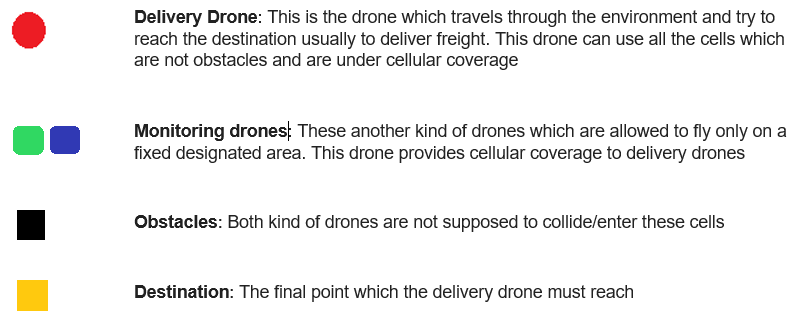

For the grid world environment:

- The search area is a 12x12 grid with obstacles.

- The observation for each agent is a 12x12x4 image.

- The discrete action set is a set of five actions (WAIT=0, UP=1, DOWN=2, LEFT=3, RIGHT=4).

- The simulation terminates when the delivery drone reaches destination or compltes 1000 steps.

At each time step, agents receive the following rewards and penalties.

- +1 for moving to a previously unexplored cell (white).

- +2 for moving closer to the destination

- +0.01 for getting closer to aerial base station

- +0.01 for getting closer to aerial base station

- -2 for moving farther from destination

- -0.01 for moving farther from monitoring drones

- -2 for an illegal action (attempt to move outside the boundary or collide against other robots and obstacles)

- -0.05 for an action that results in movement (movement cost).

- -0.1 for an action that results in no motion (lazy penalty).

- -0.1 multiplied by number of previous visits for moving to a previously explored cell

Define the locations of obstacles within the grid using a matrix of indices. The first column contains the row indices, and the second column contains the column indices.

obsMat = [4 3; 5 3; 6 3; 7 3; 8 3; 9 3; 5 11; 6 11; 7 11; 8 11; 5 12; 6 12; 7 12; 8 12];

Initialize the robot positions.

sA0 = [2 2];
sB0 = [11 4];
sC0 = [3 12];
s0 = [sA0; sB0; sC0];

Specify the sample time, simulation time, and maximum number of steps per episode.

Ts = 0.1;
Tf = 100;
maxsteps = ceil(Tf/Ts);

Open the Simulink model.

mdl = "rlAreaCoverage";
open_system(mdl)

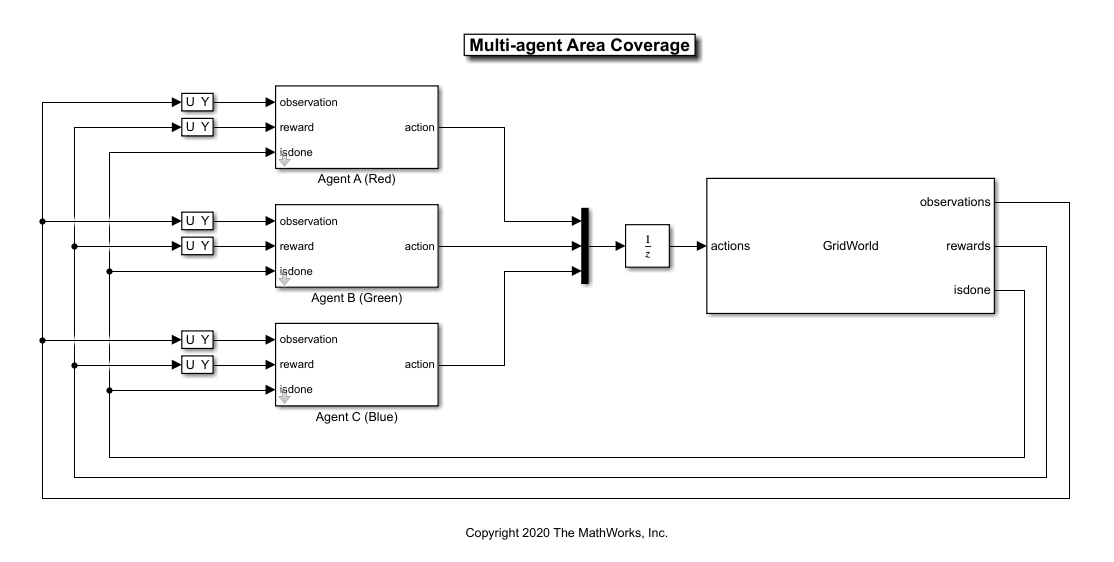

The `GridWorld` block is a MATLAB System block representing the training environment. The System object for this environment is defined in `GridWorld.m`.

In this example, the agents are homogeneous and have the same observation and action specifications. Create the observation and action specifications for the environment. For more information, see [`rlNumericSpec`](docid:rl_ref#mw_1a66fdf2-e758-4985-a541-61943fb15e79) and [`rlFiniteSetSpec`](docid:rl_ref#mw_68f70adf-d6a9-4cbe-846c-a7d0823c0774).

% Define observation specifications.
obsSize = [12 12 4];
oinfo = rlNumericSpec(obsSize);
oinfo.Name = 'observations';

% Define action specifications.
numAct = 5;
actionSpace = {0,1,2,3,4};
ainfo = rlFiniteSetSpec(actionSpace);
ainfo.Name = 'actions';

Specify the block paths for the agents.

blks = mdl + ["/Agent A (Red)","/Agent B (Green)","/Agent C (Blue)"];

Create the environment interface, specifying the same observation and action specifications for all three agents.

env = rlSimulinkEnv(mdl,blks,{oinfo,oinfo,oinfo},{ainfo,ainfo,ainfo});

Specify a reset function for the environment. The reset function `resetMap` ensures that the robots start from random initial positions at the beginning of each episode. The random initialization makes the agents robust to different starting positions and improves training convergence.

env.ResetFcn = @(in) resetMap(in, obsMat);

## Create Agents

The PPO agents in this example operate on a discrete action space and rely on actor and critic functions to learn the optimal policies. The agents maintain deep neural network-based function approximators for the actors and critics with similar network structures (a combination of convolution and fully connected layers). The critic outputs a scalar value representing the state value $V\left(s\right)$. The actor outputs the probabilities $\pi \left(a\left|s\right.\right)$ of taking each of the five actions WAIT, UP, DOWN, LEFT, or RIGHT.

Set the random seed for reproducibility.

rng(0)

Create the actor and critic functions using the following steps.

- Create the actor and critic deep neural networks.

- Create the actor function objects using the `rlDiscreteCategoricalActor` command.

- Create the critic function objects using the `rlValueFunction` command.

Use the same network structure and representation options for all three agents.

for idx = 1:3
    % Create actor deep neural network.
    actorNetWork = [
        imageInputLayer(obsSize,'Normalization','none','Name','observations')
        convolution2dLayer(8,16,'Name','conv1','Stride',1,'Padding',1,'WeightsInitializer','he')
        reluLayer('Name','relu1')
        convolution2dLayer(4,8,'Name','conv2','Stride',1,'Padding','same','WeightsInitializer','he')
        reluLayer('Name','relu2')
        fullyConnectedLayer(256,'Name','fc1','WeightsInitializer','he')
        reluLayer('Name','relu3')
        fullyConnectedLayer(128,'Name','fc2','WeightsInitializer','he')
        reluLayer('Name','relu4')
        fullyConnectedLayer(64,'Name','fc3','WeightsInitializer','he')
        reluLayer('Name','relu5')
        fullyConnectedLayer(numAct,'Name','output')
        softmaxLayer('Name','action')];
    actorNetWork = dlnetwork(actorNetWork);
    
    % Create critic deep neural network.
    criticNetwork = [
        imageInputLayer(obsSize,'Normalization','none','Name','observations')
        convolution2dLayer(8,16,'Name','conv1','Stride',1,'Padding',1,'WeightsInitializer','he')
        reluLayer('Name','relu1')
        convolution2dLayer(4,8,'Name','conv2','Stride',1,'Padding','same','WeightsInitializer','he')
        reluLayer('Name','relu2')
        fullyConnectedLayer(256,'Name','fc1','WeightsInitializer','he')
        reluLayer('Name','relu3')
        fullyConnectedLayer(128,'Name','fc2','WeightsInitializer','he')
        reluLayer('Name','relu4')
        fullyConnectedLayer(64,'Name','fc3','WeightsInitializer','he')
        reluLayer('Name','relu5')
        fullyConnectedLayer(1,'Name','output')];
    criticNetwork = dlnetwork(criticNetwork);
    
    % create actor and critic
    actor(idx) = rlDiscreteCategoricalActor(actorNetWork,oinfo,ainfo); %#ok<*SAGROW> 
    critic(idx) = rlValueFunction(criticNetwork,oinfo);
end

Specify optimizer options for the actor and critic.

actorOpts = rlOptimizerOptions('LearnRate',1e-4,'GradientThreshold',1);
criticOpts = rlOptimizerOptions('LearnRate',1e-4,'GradientThreshold',1);

Specify the agent options using [`rlPPOAgentOptions`](docid:rl_ref#mw_bf88dbd6-aa46-45cb-89a2-a786a2a9a8cc). Use the same options for all three agents. During training, agents collect experiences until they reach the experience horizon of 128 steps and then train from mini-batches of 64 experiences. An objective function clip factor of 0.2 improves training stability, and a discount factor value of 0.995 encourages long-term rewards.

opt = rlPPOAgentOptions(...
    'ActorOptimizerOptions',actorOpts,...
    'CriticOptimizerOptions',criticOpts,...
    'ExperienceHorizon',128,...
    'ClipFactor',0.2,...
    'EntropyLossWeight',0.01,...
    'MiniBatchSize',64,...
    'NumEpoch',3,...
    'AdvantageEstimateMethod','gae',...
    'GAEFactor',0.95,...
    'SampleTime',Ts,...
    'DiscountFactor',0.995);

Create the agents using the defined actors, critics, and options.

agentA = rlPPOAgent(actor(1),critic(1),opt);
agentB = rlPPOAgent(actor(2),critic(2),opt);
agentC = rlPPOAgent(actor(3),critic(3),opt);

## Train Agents

In this example, the agents are trained independently in decentralized manner. Specify the following options for training the agents.

- Automatically assign agent groups using the `AgentGroups=auto` option. This allocates each agent in a separate group.

- Specify the `"decentralized"` learning strategy.

- Run the training for at most 1000 episodes, with each episode lasting at most 5000 time steps.

- Stop the training of an agent when its average reward over 100 consecutive episodes is 80 or more.

trainOpts = rlMultiAgentTrainingOptions(...
    "AgentGroups","auto",...
    "LearningStrategy","decentralized",...
    'MaxEpisodes',10,...
    'MaxStepsPerEpisode',maxsteps,...
    'Plots','training-progress',...
    'ScoreAveragingWindowLength',100,...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',80, ...
    'Plots','training-progress'); 

For more information on multi-agent training, type `help rlMultiAgentTrainingOptions` in MATLAB.

To train the agents, specify an array of agents to the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. The order of the agents in the array must match the order of agent block paths specified during environment creation. Doing so ensures that the agent objects are linked to the appropriate action and observation specifications in the environment.

Training is a computationally intensive process that takes several minutes to complete. To save time while running this example, load pretrained agent parameters by setting `doTraining` to `false`. To train the agent yourself, set `doTraining` to `true`.

doTraining = false;
RLagent = [agentA,agentB,agentC];
if doTraining
    result = train(RLagent,env,trainOpts);
    save("UAVAgent.mat","RLagent")
else
    load('UAVAgent.mat');
end

## Simulate Agents

Simulate the trained agents within the environment. For more information on agent simulation, see [`rlSimulationOptions`](docid:rl_ref#mw_983bb2e9-0115-4548-8daa-687037e090b2) and [`sim`](docid:rl_ref#mw_e6296379-23b5-4819-a13b-210681e153bf).

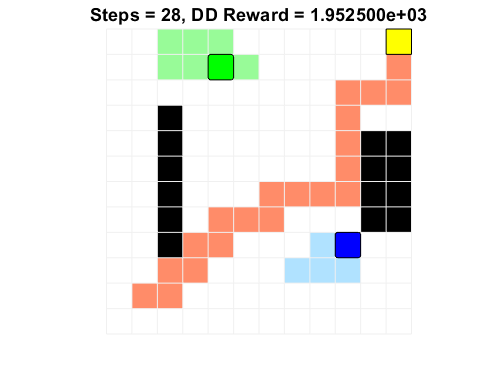

rng(1) % reset the random seed.
env.ResetFcn = @(test) testMap(test, obsMat);
simOpts = rlSimulationOptions('MaxSteps',maxsteps);
experience = sim(env,RLagent,simOpts);

The agents successfully cover the entire grid world.